# Classification of `parfor`-loops Variables

When MATLAB recognizes a name in a `parfor`-loop as a variable, the variable is classified in one of several categories: 

- [Loop Variables](https://www.mathworks.com/help/parallel-computing/loop-variable.html): Loop indices.

- [Reduction Variables](https://www.mathworks.com/help/parallel-computing/reduction-variable.html): Variables that accumulates a value across iterations of the loop, regardless of iteration order.

- [Temporary Variables](https://www.mathworks.com/help/parallel-computing/temporary-variable.html): Variables created inside the loop, and not accessed outside the loop.

- [Sliced Variables](https://www.mathworks.com/help/parallel-computing/sliced-variable.html): Arrays whose segments are operated on by different iterations of the loop.

- [Broadcast Variables](https://www.mathworks.com/help/parallel-computing/broadcast-variable.html): Variables defined before the loop whose value is required inside the loop, but never assigned inside the loop.

Make sure that your variables are uniquely classified and meet the category requirements. `parfor`-loops that violate the requirement return an error.

## Loop Variables

The loop variable defines the loop index value for each iteration. You set it in the first line of a [`parfor`](https://www.mathworks.com/help/parallel-computing/parfor.html) statement.

For values across all iterations, the loop variable must evaluate to ascending consecutive integers. Each iteration is independent of all others, and each has its own loop index value.

**Required (static)**: 

- You cannot assign to the loop variable, because changing the loop variable `p` in the `parfor` body cannot guarantee the independence of iterations. The following code is invalid because it attempts to modify the value of the loop variable `p` in the body of the loop.

- You cannot index or subscript the loop variable in any way, because referencing a field of a loop variable cannot guarantee the independence of iterations. The following code is invalid because it attempts to index the loop variable as a 1-by-1 matrix.

## Reduction Variables

A *reduction variable* accumulates a value that depends on all the iterations together, but is independent of the iteration order. MATLAB allows reduction variables in `parfor`-loops as an important exception to the rule that loop iterations must be independent. 

Reduction variables appear on both sides of an assignment statement, such as any of the following, where `expr` is a MATLAB expression

The following example shows a typical usage of a reduction variable `X`.

In a `parfor`-loop, the value of `X` is never transmitted from client to workers or from worker to worker. Rather, additions of `d(i)` are done in each worker, with `i` ranging over the subset of `1:n` being performed on that worker. The results are then transmitted back to the client, which adds the partial sums of the workers into `X`. Thus, workers do some of the additions, and the client does the rest.

**Required (static)**: 

- For any reduction variable, you must use the same reduction function or operation in all reduction assignments for that variable.

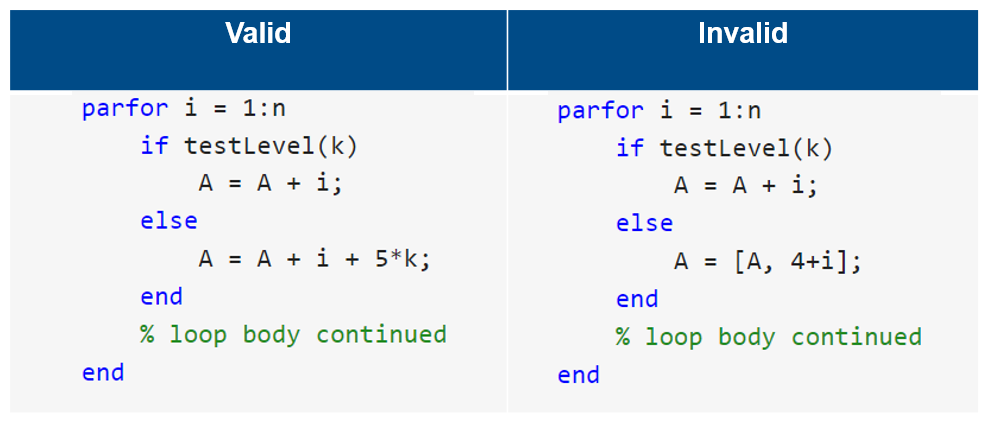

- If the reduction assignment uses `*`, `[,]`, or `[;]`, then you must consistently specify `X` as the first or second argument in every reduction assignment.

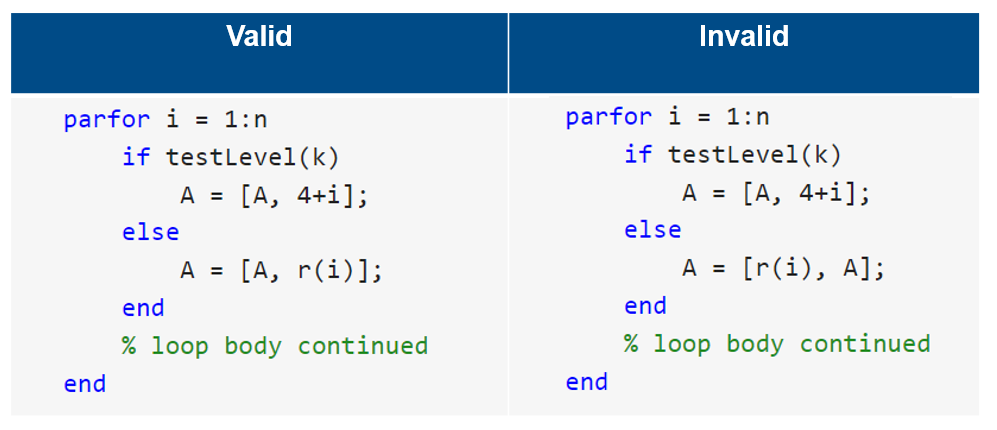

- You cannot index or subscript a reduction variable.

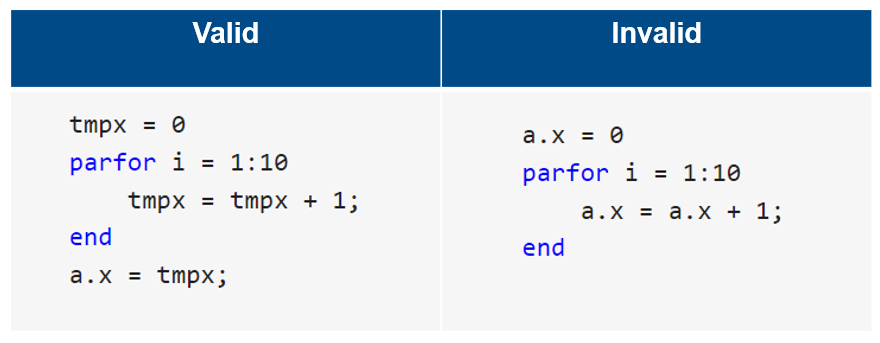

## Temporary Variables

A *temporary variable* is any variable that is the target of a direct, nonindexed assignment, but is not a reduction variable. In the following `parfor`-loop, `a` and `d` are temporary variables:

In contrast to the behavior of a [`for`](https://www.mathworks.com/help/matlab/ref/for.html)-loop

- MATLAB clears any temporary variables before each iteration of a `parfor`-loop. Therefore, temporary variables must be set inside the body of a `parfor`-loop before it is used in a loop iteration, so that an error does not occur.

- MATLAB does not send temporary variables back to the client. A temporary variable in a `parfor`-loop has no effect on a variable with the same name that exists outside the loop, because it is impossible to assign a defined value at the end of the loop to, e.g., variable `a`. Therefore, `parfor`-loop behavior is defined so that it does not affect the value `a` outside the loop. 

If you use a reduction variable elsewhere in the loop, then the variable is classfied as a temporary variable that is not initialized and an error is issued.

## Sliced Variables

A *sliced variable* is one whose value can be broken up into segments, or *slices*, which are then operated on separately by different workers. Each iteration of the loop works on a different slice of the array. **Using sliced variables can reduce communication between the client and workers.**

A variable in a `parfor`-loop is sliced if it has the following characteristics:

- The first level of indexing is either parentheses `()` or braces `{}`. After the first level, you can use any type of valid MATLAB indexing in the second and subsequent levels. 

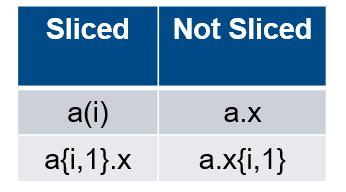

- Within the first-level parentheses or braces, the list of indices is the same for all occurrences of a given variable.

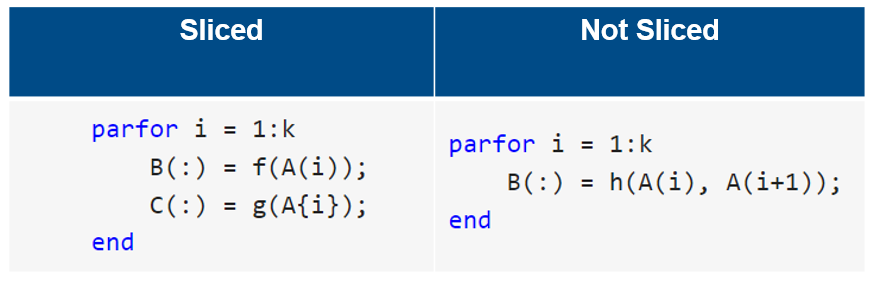

- Within the list of indices for the variable, exactly one index involves the loop variable. Every other indexing expression is a positive integer constant, a simple (non-indexed) broadcast variable, a nested `for`-loop index variable, colon, or [`end`](https://www.mathworks.com/help/matlab/ref/end.html).

    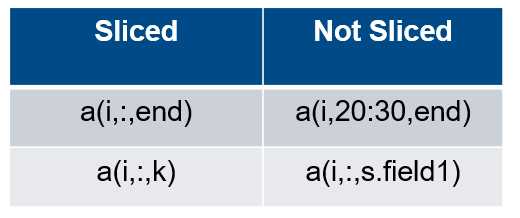

- The array maintains a constant shape. In assigning to a sliced variable, the right side of the assignment cannot be `[]` or `''`, because these operators attempt to delete elements.

*Please note a sliced variable can be an input variable, an output variable, or both: *

- Sliced input variables are transmitted from the client to the workers (unless the sliced variable elements are set before any use).

- Sliced output variables are transmitted from workers back to the client.

- If a variable is both input and output, it is transmitted in both directions.

## Broadcast Variables

A *broadcast variable* is any variable, other than the loop variable or a sliced variable, that does not change inside the loop. At the start of a `parfor`-loop, the values of any broadcast variables are sent to all workers. 

**Large broadcast variables can cause significant communication between client and workers and increase parallel overhead.** Sometimes it is more efficient to use temporary variables for this purpose, creating and assigning them inside the loop. Conversely, where computational overhead due to creating and assigning temporary variables is large, consider using broadcast variables instead.

TODO: Review the following code for opportunities to reduce communication. Can you rewrite the code to avoid sending all elements of M? 

M = magic(10);
parfor i = 1:numel(M)
    out(i) = M(i)./numel(M);
end

## Classify the following variables

Identify the variables in the following code:

counter = 0;
randVariable = randi(10);
numIterations = 10;
r = randi(10,1,numIterations);
output = zeros(1,numIterations);

parfor idx = 1:numIterations
    val = r(idx);
    if val < randVariable
        val = val + randVariable;
    end
    output(idx) = val;
    counter = counter + idx;
end

- Loop Variable: ?

- Sliced Input Variable: ?

- Sliced Output Variable: ?

- Broadcast Variable: ?

- Reduction Variable: ?

- Temporary Variable: ?

*Copyright 2023 The MathWorks, Inc.*